clf

% boilerplate / global specs
mm_to_m = 1/1000;
thickness = 9.1*mm_to_m; %4.4*mm_to_m;
width = 40*mm_to_m;

% define constants
constants = containers.Map;
constants('youngs_mod') = 29*10^9;
constants('shear_mod') = 10*10^9;
constants('shape_factor') = 6/5;

% define point force
forces = containers.Map();
F = 3800;
Fa = pi-(7*pi/180); % polar force direction

% computing force components and put into matrix
V = F*sin(Fa); 
H = F*cos(Fa);
forces('f') = [V; H];

% template for straight section
s1 = containers.Map;
s1('thickness') = thickness;
s1('length') = (100.12*2/5)*mm_to_m;
s1('width') = width;
s1('beam_angle') = 0.476; % rad]

% don't touch unless doing something fancy
s1('couple') = 0; % init
s1('boundary_angle') = 0;
s1('boundary_defV') = 0;
s1('boundary_defH') = 0;
straight1 = Straight(constants, s1);

% template for curved section
% FOR A CURVED SECTION, THE  start_angle IS THE LOADED END
c1 = containers.Map();
c1('thickness') = thickness;
c1('width') = width;
c1('radius') = (33.2/2)*mm_to_m; %m
c1('end_angle') = -pi/2+0.476;
% c1('end_angle') = -0.996;
c1('start_angle') = 0.15;
c1('boundary_angle') = 0;
c1('boundary_defV') = 0;
c1('boundary_defH') = 0;
c1('couple') = 0; % init
curved1 = Curved(constants, c1);

chonk



% store in hashmap and pass to stitch function of choice
sections = containers.Map();
sections('1') = straight1;
sections('2') = curved1;

% [x_base, y_base, x_deformed, y_deformed, moment, ang, strain_e, stiffness] = stitch_sweep(sections, forces, 'thickness', 5, [6*mm_to_m, 10*mm_to_m], 'linspace');
[x_base, y_base, x_deformed, y_deformed, moment, ang, strain_e, stiffness] = stitch(sections, forces, 'linspace');

% plotting
disp(stiffness)

$$2157.5959248334092861702557623799$$

abs_deflection = vpa(sqrt((x_base(end)-x_deformed(end))^2+(y_base(end)-y_deformed(end))^2));
disp(abs_deflection*100)

$$0.26097447829205128218958509121121$$

disp("cm")

cm


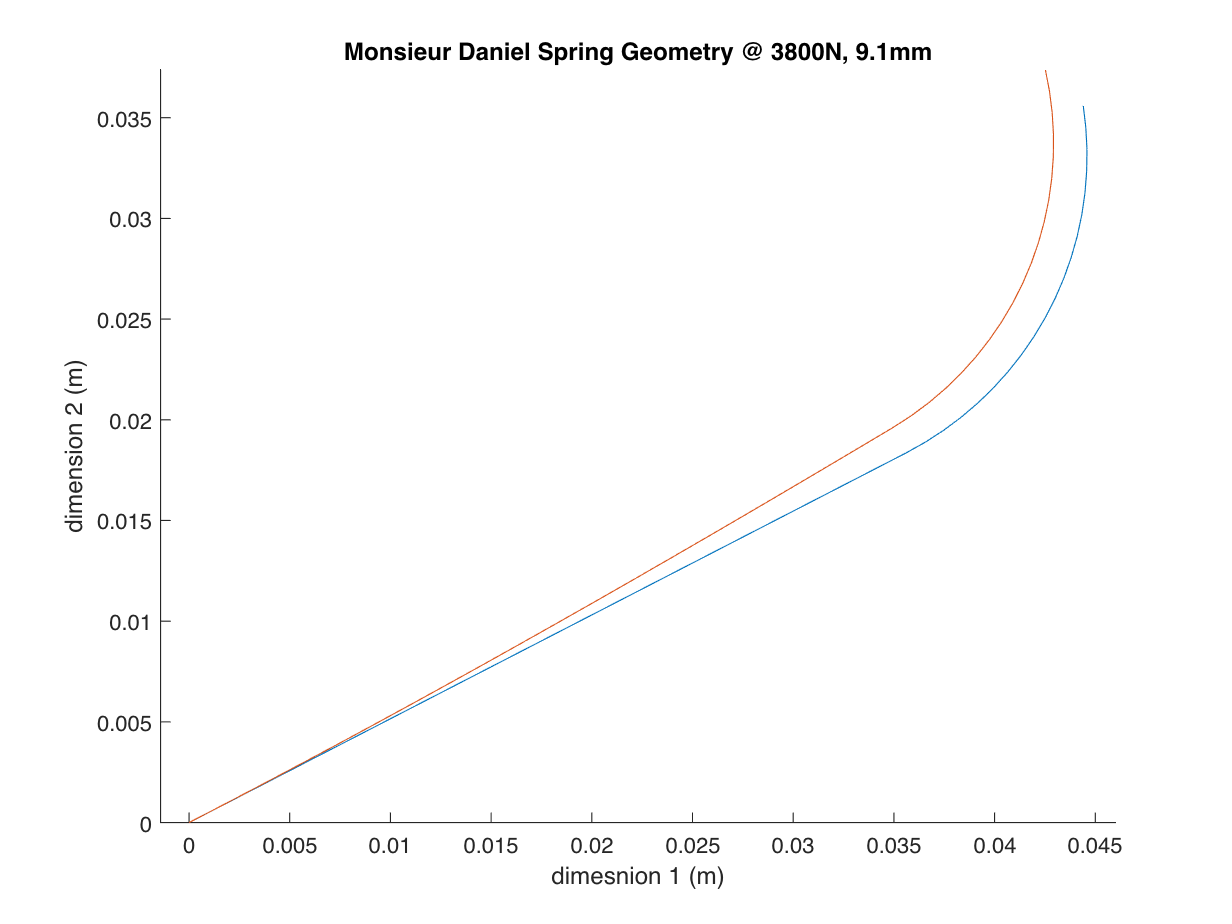

hold on
axis('equal')
plot(x_base, y_base)
plot(x_deformed, y_deformed)
title('Monsieur Daniel Spring Geometry @ 3800N, 9.1mm')
xlabel('dimesnion 1 (m)')
ylabel('dimension 2 (m)')

hold off
axis('auto')

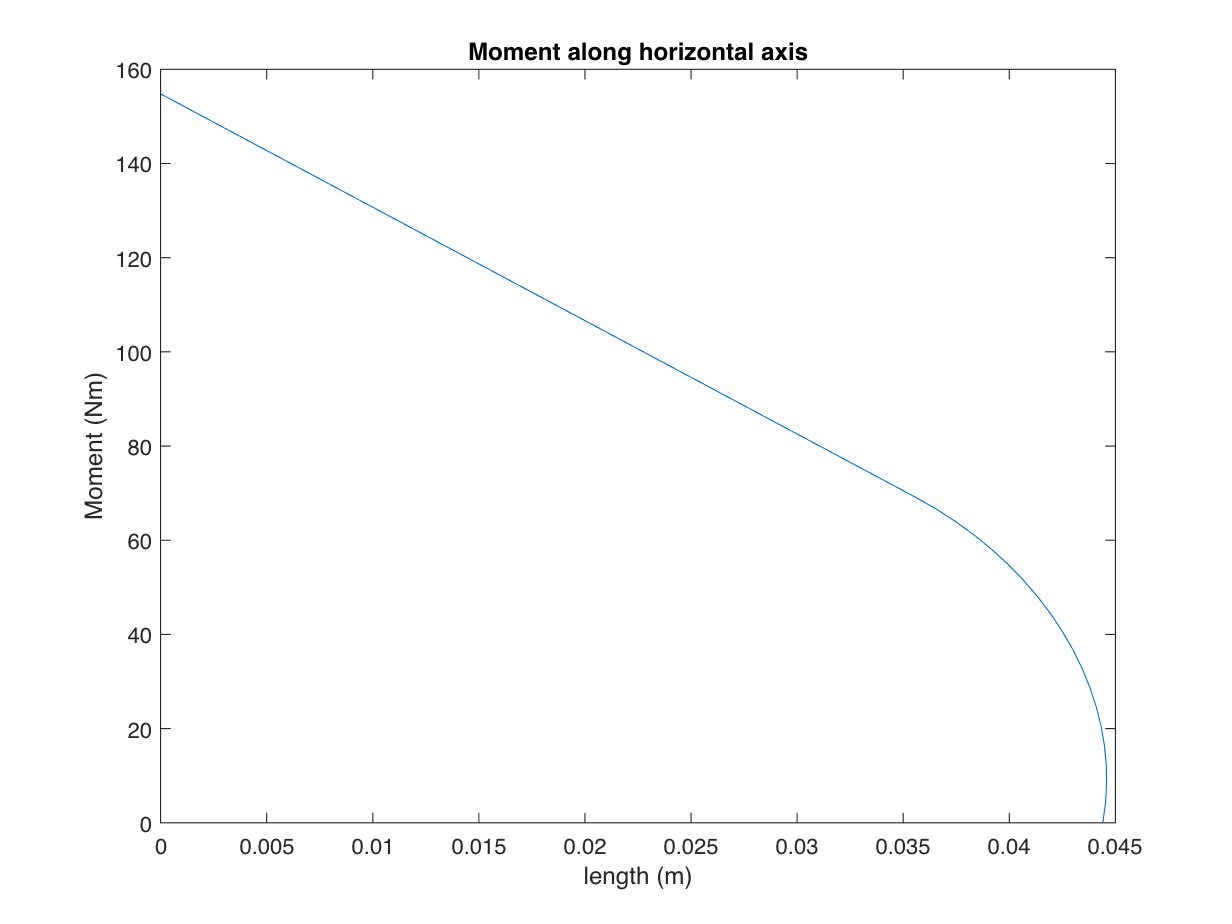

plot(x_base, moment)
title('Moment along horizontal axis')
xlabel('length (m)')
ylabel('Moment (Nm)')

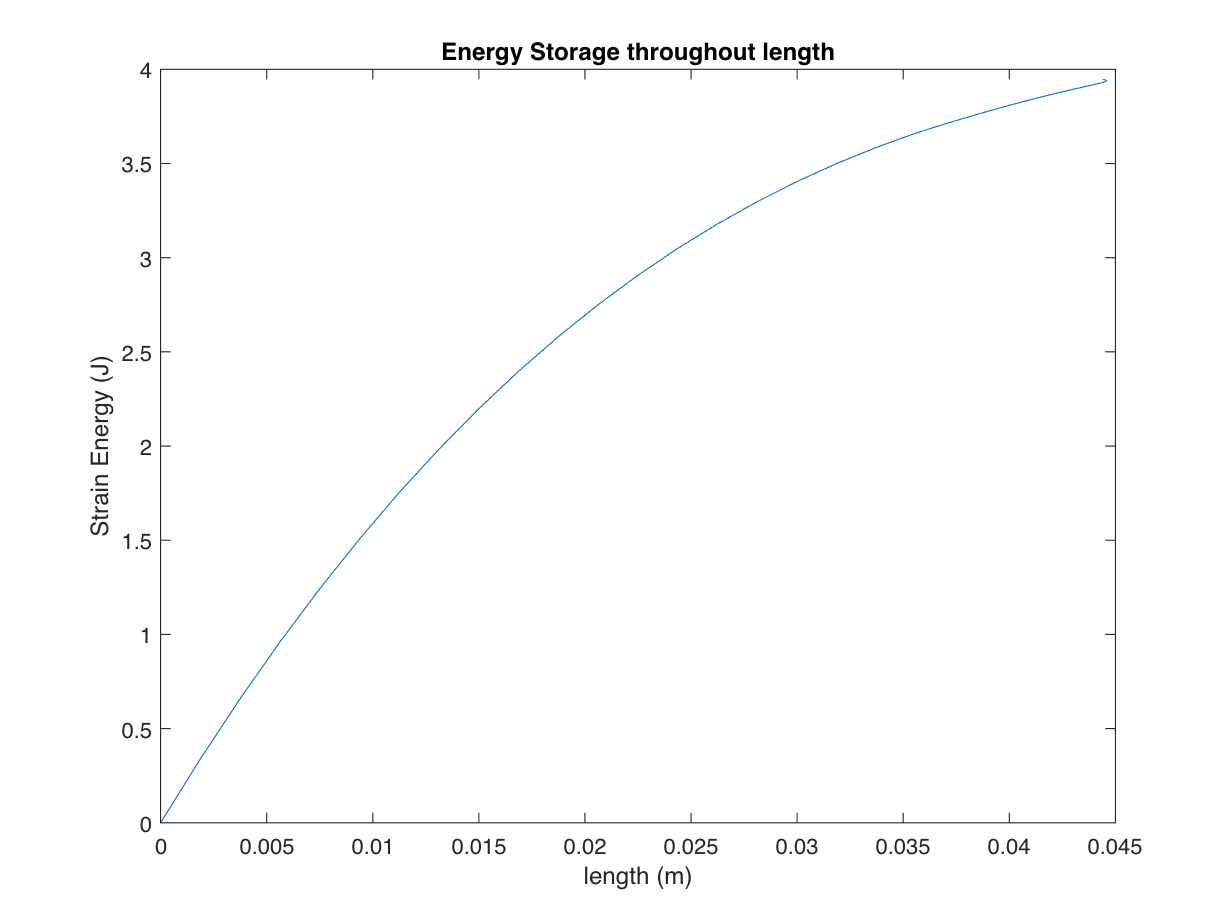

plot(x_base, strain_e)
title('Energy Storage throughout length')
xlabel('length (m)')
ylabel('Strain Energy (J)')

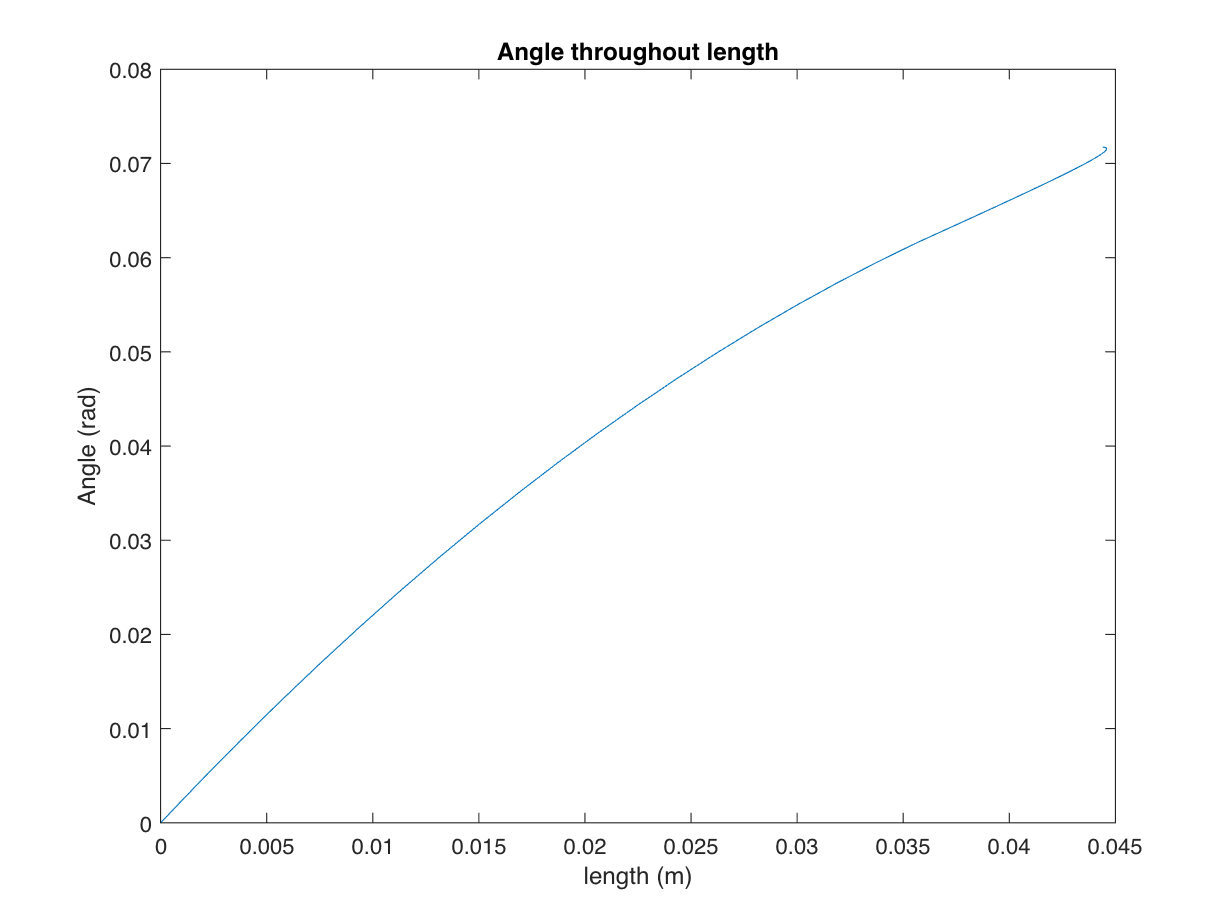

plot(x_base, ang)
title('Angle throughout length')
xlabel('length (m)')
ylabel('Angle (rad)')